clc; clearvars; close all;

%% ------------------------------------------------------------------------
% 1) Paths & setup
project_root = '../';
addpath(fullfile(project_root, 'dynamics_library'));

addpath(fullfile(project_root, 'data'));

disp('✅ Paths added.');

✅ Paths added.



% Make sure:
% - mm_M1_fun, mm_C1_fun, mm_G1_fun, mm_B1_fun, mm_R_fun
% - mm_forward_dynamics_reduced.m
% are on the path and up-to-date.

%% ------------------------------------------------------------------------
% 2) Input torques
% For pure phase portrait (natural dynamics), use zero torques:
u_fun = @(t, q, eta_dot) [0; 0; 0; 0; 0];

%% ------------------------------------------------------------------------
% 3) Indices (matching your q and eta_dot definitions)
% q = [x_m; y_m; theta_m; theta_r; theta_l; theta_1; theta_2; theta_3]
% eta_dot = [theta_r_dot; theta_l_dot; theta_1_dot; theta_2_dot; theta_3_dot]

idx.theta_r.q   = 4;  idx.theta_r.v   = 1;
idx.theta_l.q   = 5;  idx.theta_l.v   = 2;
idx.theta_1.q   = 6;  idx.theta_1.v   = 3;
idx.theta_2.q   = 7;  idx.theta_2.v   = 4;
idx.theta_3.q   = 8;  idx.theta_3.v   = 5;

% ---------------------- KEY CONTROL: interesting joints -------------------
% By default: joint 2 (theta_2) and joint 3 (theta_3)
interesting_joints = {'theta_2', 'theta_3'};
nq   = 8;
ne   = 5;

%% ------------------------------------------------------------------------
% 4) Angle and velocity grids (for ALL interesting joints together)
% angle_vals = [-pi/2, -pi/4, 0, pi/4, pi/2, 0.9*pi, pi, 1.1*pi];   % [rad]
angle_vals = [-pi/2, pi/4, pi/2, 0.9*pi, pi, 1.1*pi];   % [rad]
vel_vals   = [0, 0.5, -0.5];                                      % [rad/s]

nJ = numel(interesting_joints);
nA = numel(angle_vals);
nV = numel(vel_vals);

% --- All angle combinations across the interesting joints ---
[angle_idx_cells{1:nJ}] = ndgrid(1:nA);
num_angle_comb = numel(angle_idx_cells{1});
angle_idx_mat  = zeros(num_angle_comb, nJ);
for j = 1:nJ
    angle_idx_mat(:, j) = angle_idx_cells{j}(:);
end

% --- All velocity combinations across the interesting joints ---
[vel_idx_cells{1:nJ}] = ndgrid(1:nV);
num_vel_comb = numel(vel_idx_cells{1});
vel_idx_mat  = zeros(num_vel_comb, nJ);
for j = 1:nJ
    vel_idx_mat(:, j) = vel_idx_cells{j}(:);
end

% Total number of ICs = (angle combos) x (velocity combos)
num_IC = num_angle_comb * num_vel_comb;

%% ------------------------------------------------------------------------
% 5) Time horizon
tspan = [0 5];   % simulation horizon for each IC

%% ------------------------------------------------------------------------
% 6) Simulate all initial conditions ONCE and store results
results(num_IC) = struct('t', [], 'q', [], 'qdot', []);

ic_global = 0;
for ia = 1:num_angle_comb
    for ivc = 1:num_vel_comb
        ic_global = ic_global + 1;

        % --- Build initial state X0 = [q0; eta_dot0] ---
        q0        = zeros(nq, 1);
        eta_dot0  = zeros(ne, 1);

        for j = 1:nJ
            jname = interesting_joints{j};
            iq    = idx.(jname).q;
            iv    = idx.(jname).v;

            a_idx = angle_idx_mat(ia, j);
            v_idx = vel_idx_mat(ivc, j);

            q0(iq)       = angle_vals(a_idx);
            eta_dot0(iv) = vel_vals(v_idx);
        end

        X0 = [q0; eta_dot0];

        % --- Simulate nonlinear dynamics ---
        [t, X] = ode45(@(t,X) mm_forward_dynamics_reduced(t, X, u_fun), tspan, X0);

        q_traj       = X(:, 1:nq);
        eta_dot_traj = X(:, nq+1:end);

        % --- Recover full q_dot = R(q)*eta_dot at each step ---
        qdot_traj = zeros(size(q_traj));
        for k = 1:length(t)
            Rk = mm_R_fun(q_traj(k, :).');     % 8x5
            qdot_traj(k, :) = (Rk * eta_dot_traj(k, :).').';
        end

        % Store
        results(ic_global).t     = t;
        results(ic_global).q     = q_traj;
        results(ic_global).qdot  = qdot_traj;
    end
end

disp('✅ All trajectories simulated.');

✅ All trajectories simulated.


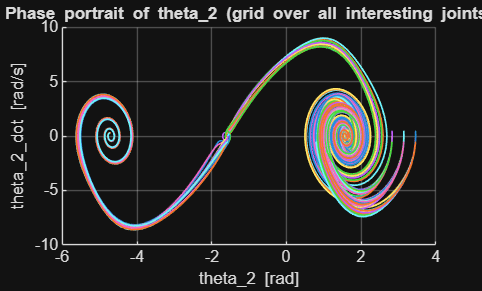

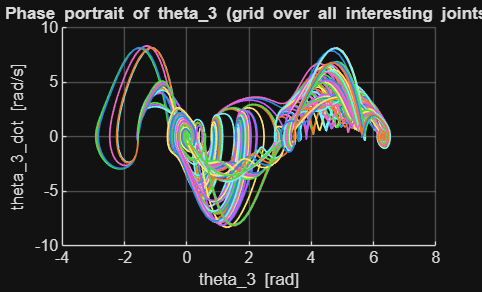


%% ------------------------------------------------------------------------
% 7) Plot phase portraits for each interesting joint
for j = 1:nJ
    jname = interesting_joints{j};
    iq    = idx.(jname).q;   % position index in q

    figure; hold on; grid on;
    cmap = lines(num_IC);

    for ic = 1:num_IC
        q_traj    = results(ic).q;
        qdot_traj = results(ic).qdot;

        theta_j     = q_traj(:, iq);
        theta_j_dot = qdot_traj(:, iq);

        plot(theta_j, theta_j_dot, 'Color', cmap(ic, :), 'LineWidth', 1.0);
    end

    xlabel(sprintf('%s [rad]', strrep(jname, '_', '\_')));
    ylabel(sprintf('%s\\_dot [rad/s]', strrep(jname, '_', '\_')));
    title(sprintf('Phase portrait of %s (grid over all interesting joints)', ...
        strrep(jname, '_', '\_')));
    hold off;
end


disp('✅ Phase portraits generated for interesting joints.');

✅ Phase portraits generated for interesting joints.
